# Funciones de trasferencia

clear, clc

g = 9.81; % gravedad
m = 1.6; % masa del dron
[I_xx, I_yy, I_zz] = deal(0.021915027, 0.022124548, 0.042349865);
kf = 0.7*9.81; % coeficiente de empuje
km = 0.2; % coeficiente de arrastre
l = 0.268554; % largo de los brazos
om_0 = sqrt(m*g/(4*kf)); % velocidad de motores con dron flotando
om_1 = sqrt(m*g/(4*km)); % velocidad de motores dron rumbo fijo
mk = log(1-0.9933)/-0.1; % retraso motores

## Controlador x

% bucle orientacion
g_the = tf(mk,[I_yy I_yy*mk 0 0]);
g_the.Numerator

ans = 1×1 cell array
    {[0 0 0 50.0565]}


g_the.Denominator

ans = 1×1 cell array
    {[0.0221 1.1075 0 0]}


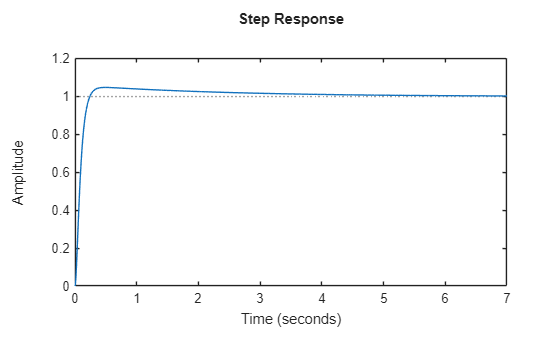

%P = 0.6*1.687;
%I = 0.6*1.687/(0.5*1.15);
%D = 0.6*1.687*1.15/8;
P = 0.12867;
I = 0.017444;
D = 0.23726;
c_the = tf([D P I],[1 0]); % D P I
step(feedback(series(c_the,g_the),1))

% bucle posicion
g_x = tf(mk*g,[I_yy I_yy*mk 0 0 0 0]);
g_xthe = (g_x*c_the)/(1+g_the*c_the);
g_xthe.Numerator

ans = 1×1 cell array
    {[0 0 0 0 2.5777 130.4273 70.1643 9.4866 0 0 0]}


g_xthe.Denominator

ans = 1×1 cell array
    {[4.8950e-04 0.0490 1.4893 13.2953 7.1523 0.9670 0 0 0 0 0]}


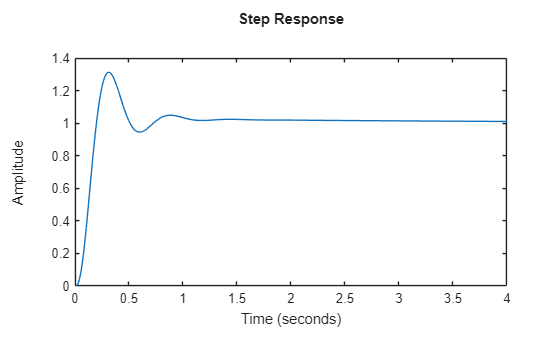

%P = 0.6*0.8606;
%I = 0.6*0.8606/(0.5*2.077);
%D = 0.6*0.8606*2.077/8;
P = 0.40202;
I = 0.036509;
D = 1.1067;
c_xthe = tf([D P I],[1 0]);
step(feedback(series(c_xthe,g_xthe),1))

## Controlador y

% bucle orientacion
g_phi = tf(mk,[I_xx I_xx*mk 0 0]);
g_phi.Numerator

ans = 1×1 cell array
    {[0 0 0 50.0565]}


g_phi.Denominator

ans = 1×1 cell array
    {[0.0219 1.0970 0 0]}


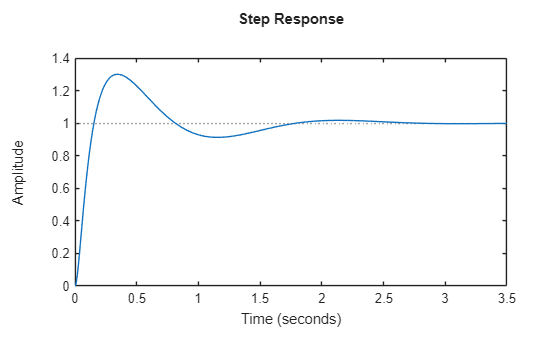

c_phi = tf([0.22482 0.7686 1.9708],[1 0]); % D P I
step(feedback(series(c_phi,g_phi),1))

% bucle posicion
g_y = tf(-mk*g,[I_xx I_xx*mk 0 0 0 0]);
g_yphi = (g_y*c_phi)/(1+g_phi*c_phi);
g_yphi.Numerator

ans = 1×1 cell array
    {[0 0 0 0 -2.4194 -129.3775 -435.2388 -1.0616e+03 0 0 0]}


g_yphi.Denominator

ans = 1×1 cell array
    {[4.8027e-04 0.0481 1.4500 13.1883 44.3669 108.2194 0 0 0 0 0]}


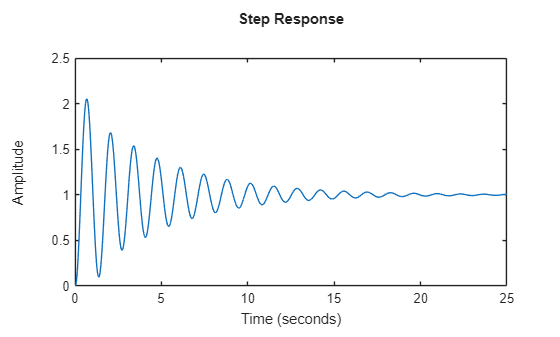

P = 0.6*2.097;
I = 0.6*2.097/(0.5*1.451);
D = 0.6*2.097*1.451/8;
c_yphi = tf([D P I],[1 0]);
step(feedback(series(-c_yphi,g_yphi),1))

## Controlador z

g_z = tf(mk,[m m*mk 0 0]);
g_z.Numerator

ans = 1×1 cell array
    {[0 0 0 50.0565]}


g_z.Denominator

ans = 1×1 cell array
    {[1.6000 80.0904 0 0]}


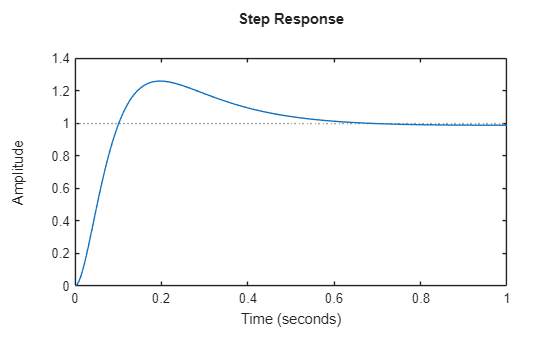

P = 0.6*212.4;
I = 0.6*212.4/(0.5*1.61);
D = 0.6*212.4*1.61/8;

c_z = tf([D P I],[1 0]);
step(feedback(series(c_z,g_z),1))